# Testing

There are two tests here, according to the Testing chapter in the report. 

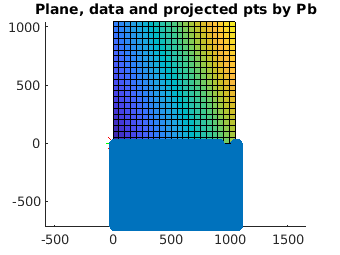

close all
clear all 

% My solution
% ptCloud = pcread('/home/diana-valeria/Documents/AAU/Semester6/P6/Implementation/testing/transformed_quadrat2_cloud.pcd');
% pcshow(ptCloud);
% point_camera4 = [-53.746696; 95.123016; 3184.565430];

% Tordivel solution
ptCloud = pcread('/home/diana-valeria/Documents/AAU/Semester6/P6/Implementation/testing/cam1.ply');
point_camera4 = [3.378586; 0.642090; -314.889404];

[X, A] = fit_plane(ptCloud);

% Visualize fitting result
[x y] = meshgrid(ptCloud.XLimits(1):50:ptCloud.XLimits(2));
z = -X(1).*x - X(2).*y - X(3);
figure;
hold on;
surf(x,y,z);
scatter3(ptCloud.Location(:, 1), ptCloud.Location(:, 2), ptCloud.Location(:, 3));
scatter3(point_camera4(1), point_camera4(2), point_camera4(3), 'Marker', '*', 'MarkerEdgeColor','g','SizeData',100);
title("Plane, data and projected pts by Pb");

% Make projection matrix
pt1 = [1; 7; -X(1)*1-X(2)*7];
pt2 = [4; -3; -X(1)*4-X(2)*(-3)];
A2 = [pt1, pt2];
P = A2/(A2'*A2)*A2';

% Project point onto the plane
plane_func = @(x,y)(-X(1)*x - X(2)*y - X(3));
p0 = [0; 0; plane_func(0,0)];
shifted_point = point_camera4-p0;
Pb = P*shifted_point + p0;

% Visualize projected point
scatter3(Pb(1,:),Pb(2, :),Pb(3, :), 'Marker', 'x', 'MarkerEdgeColor','r', 'SizeData',100);
axis equal
hold off


% Calculate the deviation
vpp = point_camera4 - Pb;
n = [X(1), X(2), 1];
distance_to_plane = sign(dot(n, vpp))*norm(vpp, 2);

% Check if unit vpp has the same magnitude as unit normal
unit_vpp = vpp / norm(vpp, 2)

unit_vpp = 3×1 single column vector
    0.0023
    0.0009
   -1.0000


unit_n = n / norm(n, 2)

unit_n = 1×3 single row vector
   -0.0023   -0.0009    1.0000


cross(unit_n, unit_vpp)

ans = 1×3 single row vector
1.0e-07 *

   -0.2276    0.1560   -0.0004


Now fit a plane through all quadrants and check deviation. 

I do that for both the current Tordivel solution, and for my solution.

This box plot is useful, as it tells, mean, max and min of non outlier data (and more). So you can compare them and see which method has higher deviation.  The outliers 

in this case is the pyramid points, and its super cool it finds and filters them. 

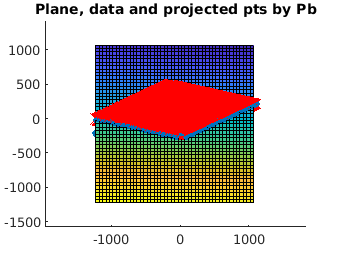

ptCloudMerged1 = pcread('/home/diana-valeria/Documents/AAU/Semester6/P6/Implementation/testing/merged_proposed_sol_test.pcd');
ptCloudMerged2 = pcread('/home/diana-valeria/Documents/AAU/Semester6/P6/Implementation/testing/merged_current_sol_test.pcd');

distance_to_plane1 = test2(ptCloudMerged1);

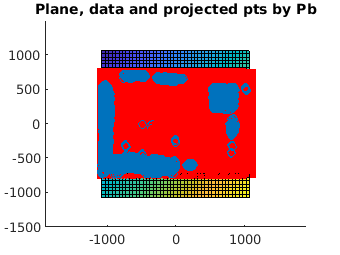

distance_to_plane_2 = test2(ptCloudMerged2);

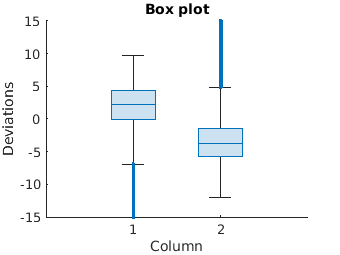


dists = [distance_to_plane1, distance_to_plane_2];

% figure;
% h = histogram(distance_to_plane2);
% title("Deviations histogram");

figure;
boxchart(dists, MarkerStyle=".");
% ylim([-10 15]) % metrascan
% ylim([-15 6]) % tordivel
ylim([-15 15]) % both
xlabel('Column')
ylabel('Deviations')
title("Box plot")

function distance_to_plane2 = test2(ptCloudMerged)
    [X2, A3] = fit_plane(ptCloudMerged);
    
    % Visualize fitting result
    [x y] = meshgrid(ptCloudMerged.XLimits(1):50:ptCloudMerged.XLimits(2));
    z = -X2(1).*x - X2(2).*y - X2(3);
    figure;
    hold on;
    surf(x,y,z);
    scatter3(ptCloudMerged.Location(:, 1), ptCloudMerged.Location(:, 2), ptCloudMerged.Location(:, 3));
    title("Plane, data and projected pts by Pb");
    
    % Make projection matrix
    pt1 = [1; 7; -X2(1)*1-X2(2)*7];
    pt2 = [4; -3; -X2(1)*4-X2(2)*(-3)];
    A2 = [pt1, pt2];
    P = A2/(A2'*A2)*A2';
    
    % Project points onto the plane
    plane_func2 = @(x,y)(-X2(1)*x - X2(2)*y - X2(3));
    p0 = [0; 0; plane_func2(0,0)];
    shifted_points = ptCloudMerged.Location'-p0;
    Pb2 = P*shifted_points + p0;
    
    % Visualize projected points
    scatter3(Pb2(1,:),Pb2(2, :),Pb2(3, :), 'Marker', 'x', 'MarkerEdgeColor','r', 'SizeData',100);
    axis equal
    hold off
    
    % Get deviations
    distance_to_plane2 = deviations(ptCloudMerged, Pb2, X2);
end

function distance_to_plane = deviations(pt_Cloud, Pb_, X_)
    % Calculate those vectors that go from the measurement pts perpendicular to
    % the plane
    vector_perp_plane = pt_Cloud.Location - Pb_';
    
    
    % the normal to the plane n = [A, B, C]. A and B were computed, C was set
    % to 1.
    n = [X_(1), X_(2), 1];
    
    % get the size of the data set
    N = pt_Cloud.Count;
    % initialize the variable that stores the deviations
    distance_to_plane = zeros(N, 1);
    for i=1:N
        vpp = vector_perp_plane(i, :);

        % dot(n, vpp) gets the projection of vpp onto the normal
        % if the normal is in the opposite direction of vpp, then
        % the sign of this result will be negative, essentially telling 
        % that the measurement point is below the surface
        % norm of vpp is the euclidean distance, aka deviation
        distance_to_plane(i) = sign(dot(n, vpp))*norm(vpp, 2);
    end
end

function [X, A] = fit_plane(ptCloud)
b = -ptCloud.Location(:,3);
A = zeros(length(b), 3);
for i = 1:length(b)
    A(i, 1) = ptCloud.Location(i, 1);
    A(i, 2) = ptCloud.Location(i, 2);
    A(i, 3) = 1;
end

% Get the plane coefficients
X = A\b;
end